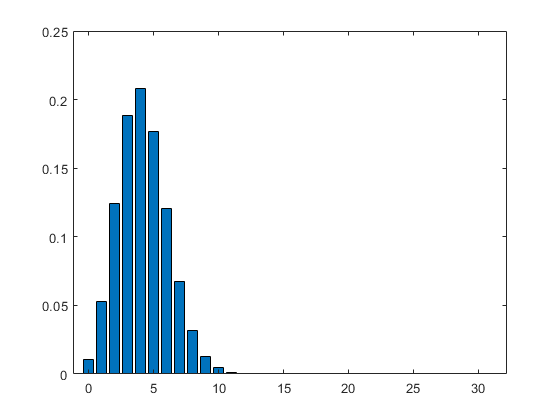

%Distribution for the binomial for the probability of getting the same
%hamming weight in various parts
N = 31;
psame = 0.1360;
k = 0 : 31;
y = binopdf(k,N,psame);
bar(k,y)

**Now, we know that for the threshold we set for euclidean distance, there is a probability of**

truePosProb = 0.5001

truePosProb = 0.5001

falsePosProb = 0.3246

falsePosProb = 0.3246

Graph the distribution for two equal operands. Then the probability is the true pos prob

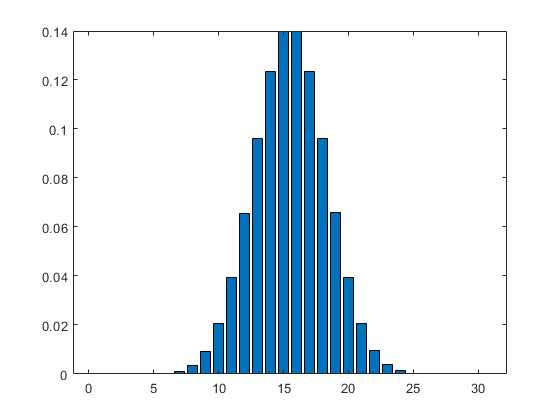

N = 31;
ytrue = binopdf(k,N,truePosProb);
bar(k,ytrue)

What is the probability of getting a one for a random operator? Probability of getting a one and classifying it well plus the probability of getting a 0 and classifying it badly. Therefore it is

prandom = psame * truePosProb + (1 - psame) * falsePosProb

prandom = 0.3485

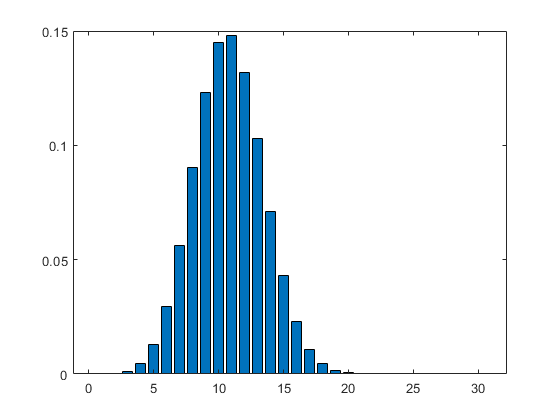

yrandom = binopdf(k,N,prandom);
bar(k,yrandom)

 Overlay both graphs

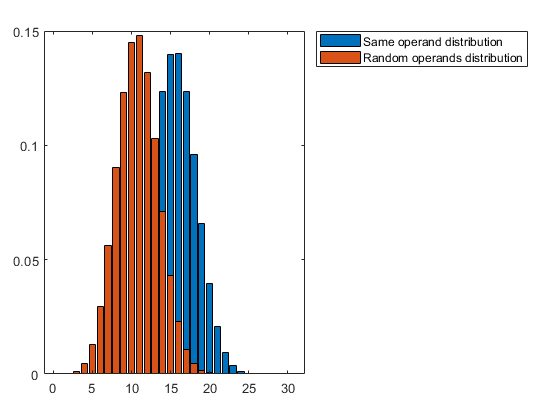

bar(k,ytrue)
hold on
bar(k,yrandom)
hold off
legend("Same operand distribution","Random operands distribution","Location","bestoutside")

Maximum likelihood, from which value ?

value = k(find(ytrue >= yrandom,1))

value = 14

In that value the probability in distribution for same operand is

ytrue(k==value)

ans = 0.1234

In the other distribution it is

yrandom(k==value)

ans = 0.0709

The cumulative probability for the most probable values (10,11,12) for random distribution is

yrandom(11)+yrandom(12)+yrandom(13)

ans = 0.4249

The cumulative probability for the most probable values (15,16,17) for same operand distribution is

ytrue(16)+ytrue(17)+ytrue(18)

ans = 0.4035

We can define the probability of getting a false positive as the cumulative probability in the random distribution such that P(k >= 14)

probTotalFalsePositive = sum(yrandom(15:end))

probTotalFalsePositive = 0.1546

Likewise, the probability of getting a true positive will be the cumulative probability in the same operand distribution such that P(k>=14)

probTotalTruePositive = sum(ytrue(15:end))

probTotalTruePositive = 0.7638

Supposing that ones are uniformly distributed in a key, then the number of positives will be the same as the number of negatives. Therefore, one can estimate the accuracy as (TP + FP) / (P + N) = TP + FP/(2P)= TP/2P + FP / 2N = TPrate/2 + (1-FPrate)/2

supposedAccuracy = probTotalTruePositive/2 + (1-probTotalFalsePositive)/2

supposedAccuracy = 0.8046

So 80.46% of accuracy. Is it enough ?

Remember we are working with P-521. That means that we have mean errors of

bitErrors = 521*(1-supposedAccuracy)

bitErrors = 101.8157

The paper from Hanley explains that the Stinson algorithm can be used to derive the key with a t-bit error in a n-bit hypothesis and they define their threshold of cost with 2^54 for practical and 2^40 for trivial. This leads to a cost of

cost = 0;
n2 = ceil(521/2);
for i = 1 : ceil(bitErrors/2)
    cost = cost + nchoosek(n2,i);
end

cost = cost * 521

cost = 4.1744e+57

Which is equivalent to 2^ to the 

exponent = log2(double(cost))

exponent = 191.4115

So is it trivial ??? I didn't expected it.

Can we calculate the ROC for our classfier? 

% XFull11 = zeros(size(X11));
% YFull11 = zeros(size(Y11));
% indexes = zeros(size(X11));
% N = 31;
% k = 0:31;
% count = 0;
% 
% for i = 1 : length(X11)
%     distTrue = makedist("Binomial","N",31,"p",Y11(i));
%     pdftrue = pdf(distTrue,0:31);
%     prandom = psame * Y11(i) + (1 - psame) * X11(i);
%     distRandom = makedist("Binomial","N",31,"p",prandom);
%     pdfrandom = pdf(distRandom,0:31);
%     if distTrue.mean > distRandom.mean %Don't take into account the cases where the mean of the true distribution is lower than random distribution
%         count = count + 1;
%         index = find(pdftrue >= prandom,1);
%         XFull11(count) = sum(pdfrandom(index:end));
%         YFull11(count) = sum(pdftrue(index:end));
%         indexes(count) = i;
%     end
% end
% XFull11 = XFull11(1:count);
% YFull11 = YFull11(1:count);
% indexes = indexes(1:count);
% 
% 
% plot(XFull11,YFull11)
% title("ROC for full clasifier with full traces and correlation")
% xlabel("False positive rate")
% ylabel("True positive rate")

% cursor_info1.Position
% supposedAccuracy2 = cursor_info1.Position(2) /2 + (1-cursor_info1.Position(1))/2
% bitErrors2 = 521*(1-supposedAccuracy2)
% cost2 = 0;
% n2 = ceil(521/2);
% for i = 1 : ceil(bitErrors2/2)
%     cost2 = cost2 + nchoosek(n2,i);
% end
% cost2 = cost2 * 521

Which is equivalent to 2^ to the 

% exponent = log2(double(cost2))

Idea : Choose classifier that has the biggest difference between means

falsePosCell = {X11 X12 X13 X14 X15 X16 X17 X18 X21 X22 X23 X24 X25 X26 X27 X28}

falsePosCell = 1×16 cell array
    {499501×1 double}    {499501×1 double}    {499501×1 double}    {499501×1 double}    {499501×1 double}    {499501×1 double}    {499501×1 double}    {499501×1 double}    {496952×1 double}    {426575×1 double}    {499500×1 double}    {433221×1 double}    {426476×1 double}    {499501×1 double}    {433499×1 double}    {499501×1 double}


truePosCell = {Y11 Y12 Y13 Y14 Y15 Y16 Y17 Y18 Y21 Y22 Y23 Y24 Y25 Y26 Y27 Y28}

truePosCell = 1×16 cell array
    {499501×1 double}    {499501×1 double}    {499501×1 double}    {499501×1 double}    {499501×1 double}    {499501×1 double}    {499501×1 double}    {499501×1 double}    {496952×1 double}    {426575×1 double}    {499500×1 double}    {433221×1 double}    {426476×1 double}    {499501×1 double}    {433499×1 double}    {499501×1 double}


selectedPoints = zeros(16,3);

%Get the best point for each one of them
for i = 1 : length(falsePosCell)
    falsePosVect = cell2mat(falsePosCell(i));
    truePosVect = cell2mat(truePosCell(i));
    for j = 1 : length(falsePosVect)
        distTrue = makedist("Binomial","N",31,"p",truePosVect(j));
        prandom = psame * truePosVect(j) + (1 - psame) * falsePosVect(j);
        distRandom = makedist("Binomial","N",31,"p",prandom);
        if abs(distTrue.mean - distRandom.mean) > selectedPoints(i,3)
            selectedPoints(i,3) = abs(distTrue.mean - distRandom.mean);
            selectedPoints(i,1) = falsePosVect(j);
            selectedPoints(i,2) = truePosVect(j);
        end
    end
end

selectedPoints

selectedPoints =     0.5543    0.7660    5.6712
    0.5601    0.6353    2.0136
    0.6041    0.7388    3.6080
    0.6293    0.7148    2.2913
    0.5664    0.6353    1.8443
    0.5962    0.6973    2.7071
    0.5905    0.6593    1.8416
    0.5117    0.5985    2.3264
    0.2430    0.4231    4.8251
    0.2262    0.3733    3.9395


[val,ind] = max(selectedPoints(:,3))

val = 5.6712

ind = 1

Which leaves the best classifier as euclidean distance with max value per clock, over synchronized traces. Let's calculate our accuracy and other rates for that classifier

ytrue = binopdf(k,N,selectedPoints(13,2));
prandom = psame * selectedPoints(13,2) + (1 - psame) * selectedPoints(13,1)

prandom = 0.2284

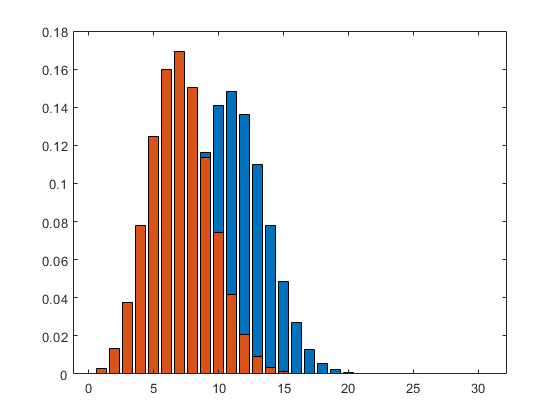

yrandom = binopdf(k,N,prandom);
bar(k,ytrue)
hold on
bar(k,yrandom)
hold off

probTotalFalsePositive = sum(yrandom(find(ytrue >= yrandom,1):end))

probTotalFalsePositive = 0.2640

probTotalTruePositive = sum(ytrue(find(ytrue >= yrandom,1):end))

probTotalTruePositive = 0.8268

accuracy = probTotalTruePositive/2 + (1-probTotalFalsePositive)/2

accuracy = 0.7814

Which gives us

bitErrors = 521*(1-accuracy)

bitErrors = 113.8884

cost = 0;
n2 = ceil(521/2);
for i = 1 : ceil(bitErrors/2)
    cost = cost + nchoosek(n2,i);
end

cost = cost * 521

cost = 1.3381e+61

Which is equivalent to 2^ to the 

exponent = log2(double(cost))

exponent = 203.0578